# Custom Train Loopによる学習

備考:  Reinforcement learning toolboxに用意されているtrain関数との比較を行い動作確認済み（状態遷移履歴の比較を行うことで実現）

clear all;
close all;
addpath('rl');

## 環境の宣言

A = [-1 2; 2.2 1.7];
B = [2; 1.6];
C = [1 2];
F = -1;

T = blkdiag(A, F);
B1 = [B; 0];
C1 = [C -1];

x0 = [5; -5; 5];

### 報酬関数の設計

Q = 6;
R = 1;

Q1 = C1'*Q*C1;

### 環境のインスタンス

env = rlDiscreteLQTEnv(A,B,C,F,Q,R,'x0',x0);
rng(0)

## エージェントの作成

### エージェントオプションの作成

K0 = [0.3 1.3 0.75];
agentOpts = rlLQTAgentOptions('StepNumPerIteration', 20, 'DiscountFactor', 0.8, 'SaveExperiences', true);

### ノイズモデルの生成

agentOpts.NoiseOptions.Mean = 0;
agentOpts.NoiseOptions.Variance = 2;

### エージェントのインスタンス

agent = rlLQTAgent(getObservationInfo(env), getActionInfo(env), agentOpts,  [0.3 1.3 0.75]);

## エージェントの学習

setStepMode(agent, "learn")
maxSteps = 500;
agent.MaxSteps = maxSteps;

% reset the environment
observation = reset(env);
reset(agent)

% get the initial action from the initial observation
action = getInitialAction(agent, observation);

for stepCnt = 1 : maxSteps
    % step the environment
    [observation,reward,isdone,loggedSignals] = step(env,action); %#ok<ASGLU>

    % step the policy
    action = step(agent,observation,reward,isdone);
end

## 学習時の経験の取り出し

% exps = agent.getExperiences();

## シミュレーション結果の検証

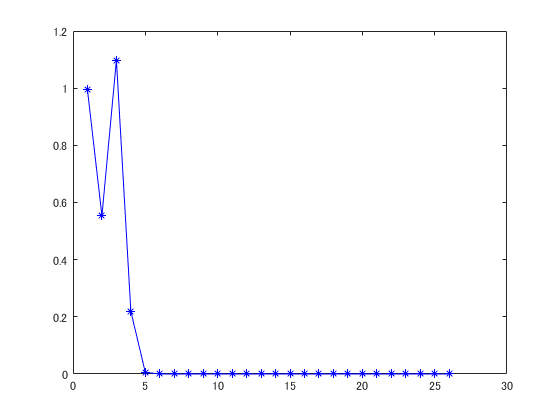

gamma = agent.AgentOptions.DiscountFactor;

A = sqrt(gamma)*T;
B = sqrt(gamma)*B1;
S = 0;
Q = Q1;
R = R;
[P, Koptimal, ~] = idare(A, B, Q, R, [], []);

err = zeros(len,1);
for i = 1:len
    % norm of error in the gain
    err(i) = norm(agent.KBuffer{i}-Koptimal);
end  
plot(err,'b*-')

gainError = norm(agent.K - Koptimal)

gainError = 2.5531e-11

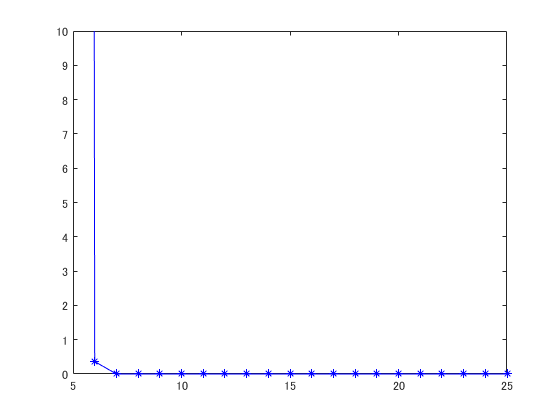

plot(agent.TDBuffer, '-b*');
ylim([0 10])